# Constant speed, straight path

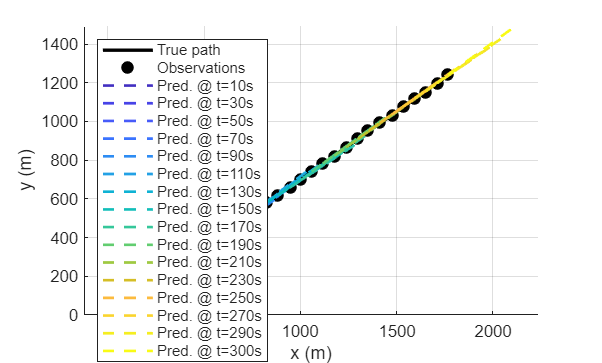

%% Sparse-AIS-style Tracking & Prediction (CV model, EKF on [x y vx vy])
% Truth: constant speed & straight heading
% Measurements: [x, y, theta]
% Filter: EKF, state = [x; y; vx; vy], h(x) = [x; y; atan2(vy, vx)]
% At each update, predict into the future and compare to truth

clear; clc; close all;

%% Scenario Parameters
Tf          = 300;        % total duration [s]
dt_truth    = 1;        % truth propagation step [s]
dt_filter   = 1;        % filter propagation step [s]
T_meas      = 10;       % measurement interval [s]
T_pred      = 60;       % prediction horizon after each update [s]

% Ground truth motion (straight line, constant velocity)
x0_true     = 0;          % m
y0_true     = 0;          % m
v_true      = 7.2;        % m/s 
theta_true  = deg2rad(35); % rad (heading from +x)
vx_true     = v_true*cos(theta_true);
vy_true     = v_true*sin(theta_true);

% Measurement noise
sigma_xy    = 3;        % m   (position)
sigma_th    = deg2rad(2); % rad (heading)

% Process noise (acceleration spectral density -> discretized Q)
sigma_a     = 0.05;       % m/s^2 (nearly-constant-velocity model)

rng(1); % reproducible

%% Truth Trajectory
t_truth = 0:dt_truth:Tf;
N_truth = numel(t_truth);
X_true  = zeros(4, N_truth);  % [x;y;vx;vy] over time
X_true(:,1) = [x0_true; y0_true; vx_true; vy_true];

for k = 2:N_truth
    dt = dt_truth;
    F  = [1 0 dt 0;
          0 1 0  dt;
          0 0 1  0;
          0 0 0  1];
    X_true(:,k) = F * X_true(:,k-1); % perfect CV truth
end

%% Measurements
% Times of measurements
t_meas = 0:T_meas:Tf;
N_meas = numel(t_meas);

% Sample truth at measurement times and add noise to [x,y,theta]
z_meas = zeros(3, N_meas); % [x; y; theta]
idx_meas_truth = round(t_meas/dt_truth) + 1; % indices into truth

for i = 1:N_meas
    kk = idx_meas_truth(i);
    x = X_true(1,kk); y = X_true(2,kk);
    vx = X_true(3,kk); vy = X_true(4,kk);
    th = atan2(vy, vx); % true heading from velocity
    z_meas(:,i) = [x + sigma_xy*randn;
                   y + sigma_xy*randn;
                   wrapToPi(th + sigma_th*randn)];
end

%% EKF Setup & Helpers
% State: x = [x; y; vx; vy]
xhat = []; Phat = [];
R    = diag([sigma_xy^2, sigma_xy^2, sigma_th^2]);

% Discretized process noise for CV with acceleration noise:
% Q = G * q * G', with q = sigma_a^2, G maps accel to state over dt.
Q_from_dt = @(dt) [ (dt^4)/4  0         (dt^3)/2  0;
                     0        (dt^4)/4  0         (dt^3)/2;
                     (dt^3)/2 0         dt^2      0;
                     0        (dt^3)/2  0         dt^2] * sigma_a^2;

F_from_dt = @(dt) [1 0 dt 0;
                   0 1 0  dt;
                   0 0 1  0;
                   0 0 0  1];

% Measurement function h(x) and Jacobian H(x)
h = @(x) [x(1);
          x(2);
          atan2(x(4), x(3))];

H_jac = @(x) [1 0 0 0;
              0 1 0 0;
              0 0 -(x(4))/(x(3)^2 + x(4)^2)   x(3)/(x(3)^2 + x(4)^2)];

wrapAng = @(a) atan2(sin(a), cos(a)); % robust wrapping

% Storage for visualization and metrics
t_filter = 0:dt_filter:Tf;
N_filt   = numel(t_filter);
X_filt   = nan(4, N_filt);
idx_meas_filt = round(t_meas/dt_filter)+1;

predictions = cell(N_meas,1);  % store predicted future paths at each update
pred_truth  = cell(N_meas,1);  % corresponding true future
pred_stats  = [];              % table of per-update prediction errors

%% Initialise filter (boot)
% Use first TWO measurements to initialise position, heading, and speed
if N_meas < 2
    error('Need at least two measurement updates to initialise speed.');
end

% Position from first measurement:
x_init = z_meas(1,1);
y_init = z_meas(2,1);

% Speed estimate from the first two position measurements:
dt12 = t_meas(2) - t_meas(1);
v_est = hypot(z_meas(1,2)-z_meas(1,1), z_meas(2,2)-z_meas(2,1)) / max(dt12,1e-6);

% Heading from second measurement (less noisy than finite diff for small moves)
th_init = z_meas(3,2);

vx_init = v_est * cos(th_init);
vy_init = v_est * sin(th_init);

xhat = [x_init; y_init; vx_init; vy_init];

% Large-ish initial covariance (uncertain speed, moderate position)
Phat = diag([sigma_xy^2*4, sigma_xy^2*4, (max(v_est,0.5))^2, (max(v_est,0.5))^2]);

%% Run EKF & Predict
meas_ptr = 1;  % will consume measurements at their timestamps
for k = 1:N_filt
    t_now = t_filter(k);

    % 1) Predict step to t_now (fixed dt here)
    Fk = F_from_dt(dt_filter);
    Qk = Q_from_dt(dt_filter);
    xhat = Fk*xhat;
    Phat = Fk*Phat*Fk' + Qk;

    % Save predicted state (before potential update)
    X_filt(:,k) = xhat;

    % 2) If a measurement arrives now, do EKF update
    if meas_ptr <= N_meas && abs(t_now - t_meas(meas_ptr)) < 1e-9
        z = z_meas(:,meas_ptr);

        % Measurement prediction
        zhat = h(xhat);
        Hk   = H_jac(xhat);

        % Innovation (careful with angle wrap on theta component)
        innov = z - zhat;
        innov(3) = wrapAng(innov(3));

        S = Hk*Phat*Hk' + R;
        K = Phat*Hk'/S;

        % State & covariance update
        xhat = xhat + K*innov;
        Phat = (eye(4) - K*Hk)*Phat;

        % 3) After update, roll out a future prediction T_pred ahead
        Np = round(T_pred/dt_filter);
        x_pred = xhat;
        P_pred = Phat;
        Fp = F_from_dt(dt_filter);
        Qp = Q_from_dt(dt_filter);

        future = zeros(4, Np+1); % includes t=0
        future(:,1) = x_pred;
        for j = 2:Np+1
            x_pred = Fp*x_pred;
            P_pred = Fp*P_pred*Fp' + Qp;
            future(:,j) = x_pred;
        end

        % Corresponding truth over that window
        t0 = t_now;
        tf = min(t_now + T_pred, Tf);
        t_pred_grid = t0:dt_filter:tf;
        idx0 = round(t0/dt_truth)+1;
        idxf = min(round(tf/dt_truth)+1, N_truth);
        truth_seg = X_true(:, idx0:idxf);

        % Save for plotting & stats
        predictions{meas_ptr} = struct('t0',t0,'dt',dt_filter,'states',future);
        pred_truth{meas_ptr}  = struct('t',t_pred_grid,'states',truth_seg);

        % Per-update prediction errors (position RMSE over the horizon)
        % Interpolate predicted positions onto truth times if needed
        % Here both use dt_filter, aligned to t0, so can align by length:
        np = min(size(future,2), size(truth_seg,2));
        pred_xy = future(1:2,1:np);
        true_xy = truth_seg(1:2,1:np);
        pos_err = vecnorm(pred_xy - true_xy, 2, 1); % Euclidean error per step [m]
        rmse_pos = sqrt(mean(pos_err.^2));
        mae_pos  = mean(abs(pos_err));

        % Speed and heading estimation at update time:
        v_est_k  = hypot(xhat(3), xhat(4));
        th_est_k = atan2(xhat(4), xhat(3));
        v_err    = v_est_k - v_true;
        th_err   = rad2deg(wrapAng(th_est_k - theta_true));

        pred_stats = [pred_stats; ...
            t_now, rmse_pos, mae_pos, v_est_k, v_err, th_est_k, th_err]; %#ok<AGROW>

        meas_ptr = meas_ptr + 1;
    end
end

%% Plots
% Plot 1
figure();
hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

% Truth path and observations
plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2, 'DisplayName', 'True path');
plot(z_meas(1,:), z_meas(2,:), 'ko', 'MarkerSize', 7, ...
     'MarkerFaceColor','k', 'DisplayName', 'Observations');

% Coloured horizons (label every 2nd, and always the last, to avoid legend spam)
n_updates = numel(predictions);
draw_idx  = 1:n_updates;                   % draw all;
colors    = parula(numel(draw_idx));       % (parula/turbo/lines)

for ii = 1:numel(draw_idx)
    i = draw_idx(ii);
    S = predictions{i};
    if isempty(S), continue; end
    xy = S.states(1:2,:);
    if mod(i,2)==0 || i==draw_idx(end)
        lbl = sprintf('Pred. @ t=%.0fs', round(t_meas(i)));
        vis = 'on';
    else
        lbl = '';
        vis = 'off';
    end
    plot(xy(1,:), xy(2,:), '--', 'Color', colors(ii,:), ...
         'LineWidth', 1.6, 'DisplayName', lbl, 'HandleVisibility', vis);
end

legend('Location','northwest');

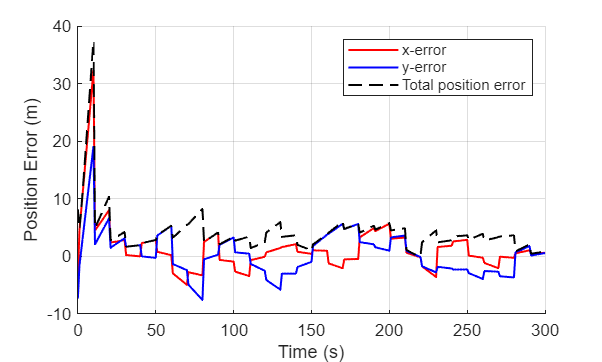


% Plot 2
%% Compute and Plot Position Error
% Interpolate EKF filtered estimates onto truth time grid for fair comparison
valid_idx = find(all(~isnan(X_filt(1:2,:)),1));
t_valid   = t_filter(valid_idx);
x_filt_i  = interp1(t_valid, X_filt(1,valid_idx), t_truth, 'linear', 'extrap');
y_filt_i  = interp1(t_valid, X_filt(2,valid_idx), t_truth, 'linear', 'extrap');

% Compute position error components
x_err = X_true(1,:) - x_filt_i;
y_err = X_true(2,:) - y_filt_i;
pos_err_total = sqrt(x_err.^2 + y_err.^2);

% Plot errors
figure('Color','w'); hold on; grid on;
plot(t_truth, x_err, 'r', 'LineWidth', 1.2);
plot(t_truth, y_err, 'b', 'LineWidth', 1.2);
plot(t_truth, pos_err_total, 'k--', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Position Error (m)');
legend({'x-error','y-error','Total position error'}, 'Location','northeast');

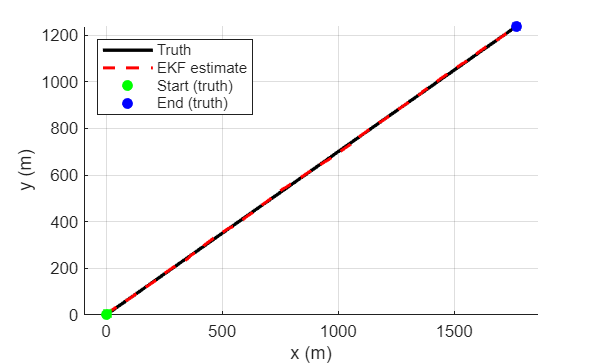


% Plot 3
% Trajectory comparison (x–y): Truth vs EKF estimates
figure(); clf; hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

% True trajectory (from X_true built earlier)
plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2, 'DisplayName','Truth');

% EKF trajectory (from X_filt built during filtering)
% Keep only valid (non-NaN) samples
valid_idx = find(all(~isnan(X_filt(1:2,:)),1));
x_est = X_filt(1, valid_idx);
y_est = X_filt(2, valid_idx);
plot(x_est, y_est, 'r--', 'LineWidth', 1.8, 'DisplayName','EKF estimate');

% Start/end markers
plot(X_true(1,1),      X_true(2,1),      'go', 'MarkerFaceColor','g', 'DisplayName','Start (truth)');
plot(X_true(1,end),    X_true(2,end),    'bo', 'MarkerFaceColor','b', 'DisplayName','End (truth)');
plot(x_est(1),         y_est(1),         'gs', 'MarkerFaceColor','g', 'HandleVisibility','off');  % start (EKF)
plot(x_est(end),       y_est(end),       'bs', 'MarkerFaceColor','b', 'HandleVisibility','off');  % end (EKF)

legend('Location','northwest');


%% Console Stats
if ~isempty(pred_stats)
    % Columns: [t_update, RMSE_pos, MAE_pos, v_est, v_err, th_est, th_err_deg]
    mean_rmse = mean(pred_stats(:,2));
    median_rmse = median(pred_stats(:,2));
    mean_mae  = mean(pred_stats(:,3));
    last_row  = pred_stats(end,:);

    fprintf('--- Prediction Summary (H=%.0f s, updates every %.0f s) ---\n', T_pred, T_meas);
    fprintf('True speed      : %.3f m/s (%.2f kn)\n', v_true, v_true*1.94384);
    fprintf('True heading    : %+6.2f deg\n', rad2deg(theta_true));
    fprintf('Avg RMSE (pos)  : %.3f m\n', mean_rmse);
    fprintf('Med RMSE (pos)  : %.3f m\n', median_rmse);
    fprintf('Avg MAE (pos)   : %.3f m\n', mean_mae);

    fprintf('\nLast update at t=%.0f s:\n', last_row(1));
    fprintf('  Pred. speed   : %.3f m/s (err = %+6.3f m/s)\n', last_row(4), last_row(5));
    fprintf('  Pred. heading : %+6.2f deg (err = %+6.2f deg)\n', rad2deg(last_row(6)), last_row(7));
    fprintf('  Horizon RMSE  : %.3f m\n', last_row(2));
else
    fprintf('No prediction stats computed (insufficient updates?).\n');
end

--- Prediction Summary (H=60 s, updates every 10 s) ---


True speed      : 7.200 m/s (14.00 kn)


True heading    : +35.00 deg


Avg RMSE (pos)  : 11.228 m


Med RMSE (pos)  : 5.944 m


Avg MAE (pos)   : 10.195 m



Last update at t=300 s:


  Pred. speed   : 7.190 m/s (err = -0.010 m/s)


  Pred. heading : +35.79 deg (err =  +0.79 deg)


  Horizon RMSE  : 2.941 m



%% Helpers
function xnext = propagate_sv(x, dt)
    % x = [x; y; v; psi; a]  (straight line; a constant over dt)
    xn = x; v = xn(3); psi = xn(4); a = xn(5);
    dv = a*dt;
    ds = v*dt + 0.5*a*dt^2;
    xnext = [ xn(1) + ds*cos(psi);
              xn(2) + ds*sin(psi);
              max(0, v + dv);
              wrap(xn(4));      % heading ~ constant (only noise via process)
              a ];              % acceleration random walk handled by Q
end

function F = numJacobian(f, x)
    n = numel(x); fx = f(x); m = numel(fx);
    F = zeros(m,n); eps = 1e-6;
    for i = 1:n
        dx = zeros(n,1); dx(i) = eps;
        F(:,i) = (f(x+dx) - fx)/eps;
    end
end

function a = wrap(a), a = atan2(sin(a), cos(a)); end